-     Use Matlab’s integral function to evaluate the following integral.

                

disp('------------------------------------ Q1 --------------------------------------------')

------------------------------------ Q1 --------------------------------------------


q1()

        1104



2. Use Matlab’s trapz function to determine the distance travelled as recorded in the following data table of velocity and time.

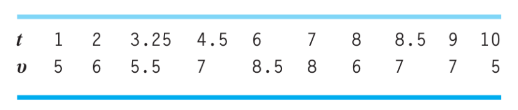

disp('------------------------------------ Q2 --------------------------------------------')

------------------------------------ Q2 --------------------------------------------


q2()

   60.1250



3. Use any Matlab functions to fit a cubic polynomial to the data in Question 2 then calculate it’s integral over the given time domain. How does it compare with the trapezium rule estimate in Matlab?

disp('------------------------------------ Q3 --------------------------------------------')

------------------------------------ Q3 --------------------------------------------


q3()

   60.0224



4. The total mass of a variable density rod is given by,

        

where *m* is mass, *ρ* is density, *Ac* is cross-sectional area, *x* is the distance along the rod, and *L* is the total length of the rod. The following data was taken from a 20 m rod. Determine the mass in grams of the rod.

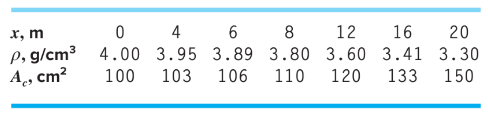

disp('------------------------------------ Q4 --------------------------------------------')

------------------------------------ Q4 --------------------------------------------


q4()

The mass is 8631.35


5. Write a function file that implements the composite trapezium rule. The inputs should be the function to be integrated, a starting point, an end point, and a number of segments.

disp('------------------------------------ Q5 --------------------------------------------')

------------------------------------ Q5 --------------------------------------------


f = @(x) 0.2 + 25*x - 200*(x.^2) + 675*(x.^3) - 900*(x.^4) + 400*(x.^5);
output = comp_trapz(f, 0, 0.8, 2)

output = 1.0688

6. Write a function file that implements the composite Simpson’s 1/3 rule. The inputs should be the function to be integrated, a starting point, an end point, and a number of segments. Your function should check that the user provided an even number of segments (consider what default behaviour you will do if there are an odd number of segments).

disp('------------------------------------ Q6 --------------------------------------------')

------------------------------------ Q6 --------------------------------------------


f = @(x) 0.2 + 25*x - 200*(x.^2) + 675*(x.^3) - 900*(x.^4) + 400*(x.^5);
output = comp_simpson(f, 0, 0.8, 5)

Odd number of intervals entered. Combining 1/3 and 3/8 rule.


output = 1.6451

7. Write a function file that implements the trapezium rule **for unequal spacing**. The inputs should be 2 vectors of data. Be sure to check that the number of data points in each vector is the same.

disp('------------------------------------ Q7 --------------------------------------------')

------------------------------------ Q7 --------------------------------------------


x = [0, 0.12, 0.22, 0.32, 0.36, 0.4, 0.44, 0.54, 0.64, 0.7, 0.8]

x =          0    0.1200    0.2200    0.3200    0.3600    0.4000    0.4400    0.5400    0.6400    0.7000    0.8000


y = [0.2, 1.309729, 1.305241, 1.743393, 2.074903, 2.456, 2.842985, 3.507297, 3.181929, 2.363, 0.232]

y =     0.2000    1.3097    1.3052    1.7434    2.0749    2.4560    2.8430    3.5073    3.1819    2.3630    0.2320


output = unequal_trapz(x, y)

output = 1.5948

8. Adapt your trapezium rule function file for unequal spacing to **sort the data** in case the data for the independent variable is not provided in a monotonically ascending vector.

disp('------------------------------------ Q8 --------------------------------------------')

------------------------------------ Q8 --------------------------------------------


x = [0, 0.12, 0.22, 0.32, 0.36, 0.4, 0.44, 0.54, 0.64, 0.7, 0.8]

x =          0    0.1200    0.2200    0.3200    0.3600    0.4000    0.4400    0.5400    0.6400    0.7000    0.8000


y = [0.2, 1.309729, 1.305241, 1.743393, 2.074903, 2.456, 2.842985, 3.507297, 3.181929, 2.363, 0.232]

y =     0.2000    1.3097    1.3052    1.7434    2.0749    2.4560    2.8430    3.5073    3.1819    2.3630    0.2320


output = sort_unequal_trapz(x, y)

output = 1.5948

---------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------

function q1()
    f = @(x) 1 - x - 4*x.^3 + 2*x.^5;
    disp(integral(f, -2, 4))
end


function q2()
    t = [1, 2, 3.25, 4.5, 6, 7, 8, 8.5, 9, 10];
    v = [5, 6, 5.5, 7, 8.5, 8, 6, 7, 7, 5];
    disp(trapz(t, v))
end


function q3()
    t = [1, 2, 3.25, 4.5, 6, 7, 8, 8.5, 9, 10];
    v = [5, 6, 5.5, 7, 8.5, 8, 6, 7, 7, 5];

    p = polyfit(t, v, 3); % coefficient fo cubic
    f = @(t) t.^3 * p(1) + t.^2 * p(2) + t * p(3) + p(4);      % cubic poly function
    disp(integral(f, min(t), max(t)));                          % range of x
end


function q4()
    x = [0, 4, 6, 8, 12, 16, 20];
    p = [4.00, 3.95, 3.89, 3.80, 3.60, 3.41, 3.3];
    A = [100, 103, 106, 110, 120, 133, 150];
    
    % find value of y
    y = p.*A;

    % calculate mass using trapezoid
    mass = trapz(x, y);

    % Display mass with two decimal places
    fprintf('The mass is %.2f\n', mass);            
end

functions


function I_trapz = comp_trapz(f, a, b, n)
    % func: The function to be integrated
    % a: Starting point of the interval
    % b: End point of the interval
    % n: Number of segments

    % Calculate the step size
    h = (b-a)/n;

    x = linspace(a, b, n + 1);      % Generate values of x including both endpoints
    fx = 2*sum(f(x(2:end-1)));
    I_trapz = (h/2) * (f(a) + fx + f(b));
end

function I_simpson = comp_simpson(f, a, b, n)
    % if n = even number and more than 1
    % apply simpson 1/3
    if mod(n, 2) == 0 && n > 1
        h = (b-a)/n;
        x = a:h:b;
        disp(f(x(2:2:end-1)))
        I_simpson = (h/3) * ( f(a) + 4*f(x(2:2:end-1)) + 2*sum(f(x(3:2:end-2))) + f(b) );
    
    % 3 points -> 3/8 rules
    elseif n == 3
        h = (b-a)/n;
        x = a:h:b;
        I_simpson = ( (b-a)/8 ) * ( f(a) + 3*f(x(2)) + 3*f(x(3)) + f(b) );

    elseif n > 3
        disp('Odd number of intervals entered. Combining 1/3 and 3/8 rule.');
        h = (b-a)/n;
        x = a:h:b;
        I_simpson = ((h/3) * ( f(a) + 4*f(x(2:2:end-4)) + 2*sum(f(x(3:2:end-5))) + f(x(end-3)) )) + ( (b-x(end-3))/8 ) * ( f(x(end-3)) + 3*f(x(end-2)) + 3*f(x(end-1))+ f(b) );
    end
end


function integral = unequal_trapz(x, y)
    %{
    Implements the trapezium rule for unequally spaced data:
    A = (h1/2)*(f(x0)+f(x1)) + (h2/2)*(f(x1)+f(x2)) + ...
    %}

    % Check if vectors are the same length and are ordered
    if length(x) ~= length(y)
       % If vectors are different lengths display a message to the user
       disp('2 vectors are in different length')
    else
        n = length(x);

        % Initialize the integral
        integral = 0;
    
        % Calculate the integral using the trapezoidal rule
        for i = 1:n-1
            h = x(i+1) - x(i);
            integral = integral + 0.5 * h * (y(i) + y(i+1));
        end
    end
end


function integral = sort_unequal_trapz(x, y)
    % x: Vector of x-values (unequal spacing)
    % y: Vector of corresponding function values

    % Check if the number of data points in x and y is the same
    if length(x) ~= length(y)
        error('The number of data points in x and y must be the same.');
    end

    n = length(x);  % Number of data points

    % Sort the data in ascending order of x
    % sort(x, 'descend'); for descend
    [x, idx] = sort(x);         % ascending value of x
    y = y(idx);                 % x indices stored in idx, get corresponding y of previous x

    % Initialize the integral
    integral = 0;

    % Calculate the integral using the trapezoidal rule
    for i = 1:n-1
        h = x(i+1) - x(i);
        integral = integral + 0.5 * h * (y(i) + y(i+1));
    end
end
